# VALIDACION DE SEÑALES PRACTICAS

#### **VALIDACION EN LAZO ABIERTO**

%Primero vamos a Sacar las señales
% primero el nombre de el archivo con el que se exporto la espacio de
% trabajo , en signals(posicion)

t=P1LCI.time; %aqui para tiempo

y2=P1LCI.signals(5).values(:); %aqui para la señal de salida
u=P1LC.signals(3).values(:); %aqui para la señal de entrada
%G=zpk([],[-2 -10],40) %aqui definimos la funcion de transferencia(en este caso tenemos una con dos polos reales
%Primera Planta LAB#2
s=tf('s');
G1=1/(0.5*s+1)

G1 =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



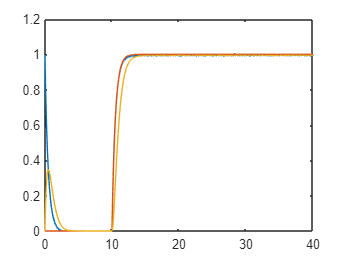


yi=lsim(G1,u,t); %para poder graficar la funcion de transferencia de el sistema

plot(t,u,'DisplayName','u');hold on;plot(t,y2,'DisplayName','y');plot(t,yi,'DisplayName','yi');hold off;

#### **VALIDACION EN LAZO CERRADO CON RETROALIMENTACION**


t2=P1LCI.time;%sacamos la variable de tiempo
u2=P1LCI.signals(2).values(:);%sacamos la señal de entrada
y2=P1LCI.signals(5).values(:);%sacamos la señal de salida /la señal real
e=P1LCI.signals(3).values(:);
s=tf('s');
G1=1/(0.5*s+1)

G1 =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



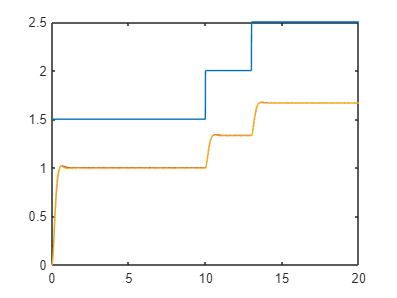

Gi1=feedback(G1,1);%Retroalimentamos la funcion de transferencia
yi1=lsim(Gi1,u,t);%para graficar nuestra funcion de transferencia/salida ideal
plot(t2,u2,'DisplayName','u2');hold on;plot(t2,yi1,'DisplayName','yi2');plot(t2,y2,'DisplayName','y2');hold off;

#### **VALIDACION EN LAZO CERRADO , CON RETROALIMENTACION Y GANANCIA (P3)**

tp2=P3G2.time;%sacamos tiempo

Unable to resolve the name P3G2.time.

up2=P3G2.signals(2).values(:);%señal de la ganacia
yidealp2=P3G2.signals(1).values(:);%salida de el sistema/respuesta REAL
rp2=P3G2.signals(3).values(:);% señal de referencia de entrada(escalon)

G2=zpk([],[-2 -5],30)%funcion de transferencia de el sistema

Gi1=feedback(G,1); %retroalimentacion de la funcion de transferencia
%para obtener la respuesta ideal , lsim + TF+ señal de la ganacia + tiempo
Gi1I=Gi1*1/s;
yideal2=lsim(Gi1I,up2,tp2);% respuesta IDEAL de el sistema

plot(up2,'DisplayName','u3g2');hold on;plot(yidealp2,'DisplayName','yig2');plot(yideal2,'DisplayName','yiP3G2');plot(rp2,'DisplayName','r3');hold off;

#### **PLANTA#2**

**LAZO ABIERTO**

A=input('Introduzca el nombre de el archivo: ');

t=A.time; %aqui para tiempo

y2=P1LA.signals(1).values(:); %aqui para la señal de salida
u=P1LA.signals(2).values(:); %aqui para la señal de entrada
%G=zpk([],[-2 -10],40) %aqui definimos la funcion de transferencia(en este caso tenemos una con dos polos reales
%Primera Planta LAB#2
s=tf('s');
G1=1/(0.5*s+1)

yi=lsim(G1,u,t); %para poder graficar la funcion de transferencia de el sistema

plot(t,u,'DisplayName','u');hold on;plot(t,y2,'DisplayName','y');plot(t,yi,'DisplayName','yi');hold off;